clear

% Bilderna sökväg
imagePath = '../HDR/ImagesSmall/';

% Alla tiff-filer i mappen
imageList = dir(fullfile(imagePath, '*.tiff'));
imageAmount = numel(imageList);


%Första bilden
firstImage = im2double(imread(fullfile(imagePath, imageList(1).name)));

% Hämta storleken på den första bilden
[row, col, channel] = size(firstImage);

%Initialize allImages
allImages = zeros(row, col, channel, imageAmount);

%Sparar alla bilder i allImages
for i = 1:imageAmount
    allImages(:,:,:,i) = im2double(imread(fullfile(imagePath, imageList(i).name)));
end


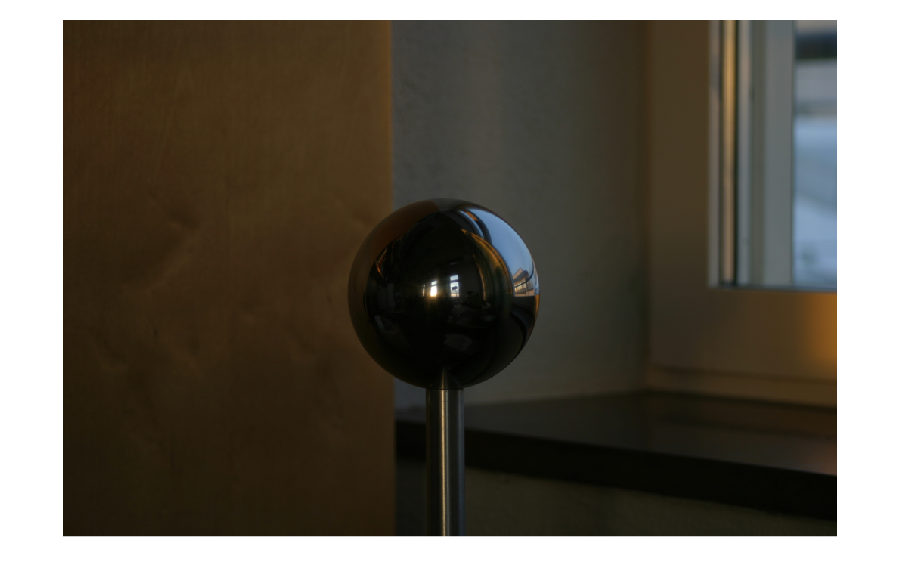

figure;
imshow(allImages(:,:,:,14));

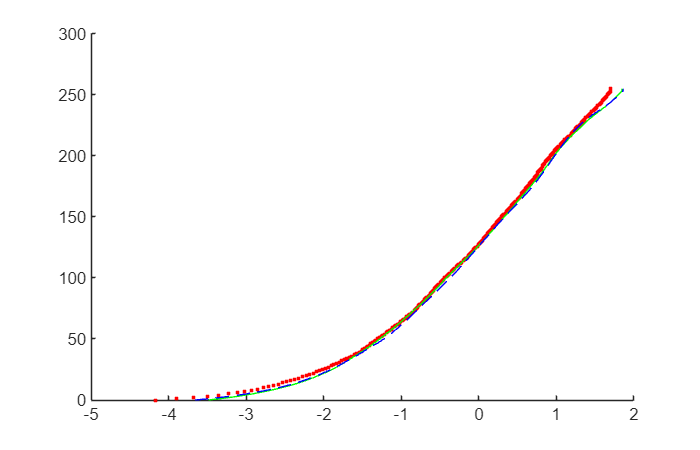

image = allImages(:,:,:,14);

% Dela upp RGB-kanalerna i imOG:
[R,G,B] = imsplit(image);

% Gör R-kanalen till en 1D-vektor, kalla den imJ:
imJ = R(:);

% Pixel location i:
locI = imJ(1);

gCurve = makegfun;
y = linspace(0, 255, 256)';

%[gCurve,lE] = gsolve(Z,B,l,w)

figure;
hold on;
plot(gCurve(:,1), y, 'r.');
plot(gCurve(:,2), y, 'g-');
plot(gCurve(:,3), y, 'b--');